# Setup data

data = readmatrix("Mathematics/Topic1-4/MMA I CW I Dataset.xlsx");
courseworkMarks = data(:,1);
examMarks = data(:,2);

# a

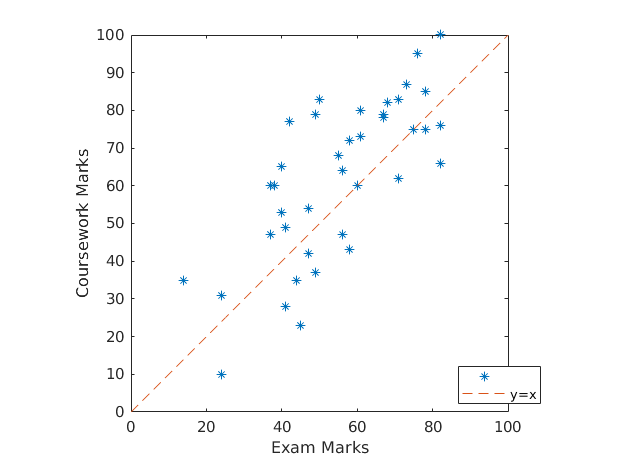

figure,plot(examMarks,courseworkMarks, '*');
xlabel('Exam Marks'); ylabel('Coursework Marks')
axis square; axis ([0 100 0 100])
hold on; plot(0:100,0:100, '--'); hold off;
legend('', 'y=x', 'Location', 'best');
print('eps/topic1_a.eps','-depsc')

# b

figure,plot(examMarks,courseworkMarks, '*');
xlabel('Exam Marks'); ylabel('Coursework Marks')
i=0:100

i =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


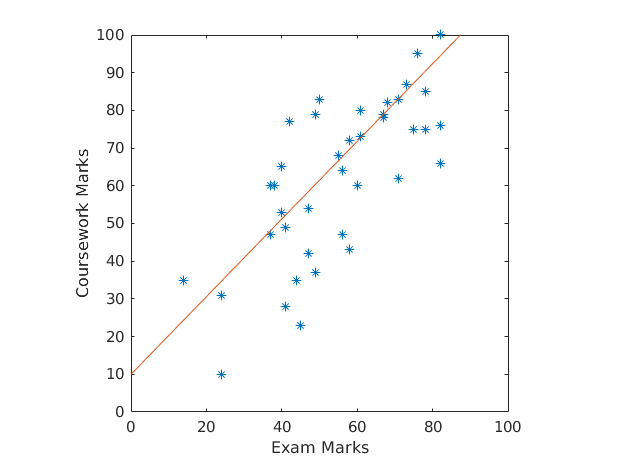

hold on; plot(i,10+i.*1.03);
axis square; axis ([0 100 0 100]);
hold off;
print('eps/topic1_b.eps','-depsc')

# c

figure,plot(examMarks,courseworkMarks, '*');
xlabel('Exam Marks'); ylabel('Coursework Marks')
hold on;
axis square; axis ([0 100 0 100]);

p=polyfit(examMarks, courseworkMarks, 1) %Generate polynomial of best fit

p =     0.8950   12.7990


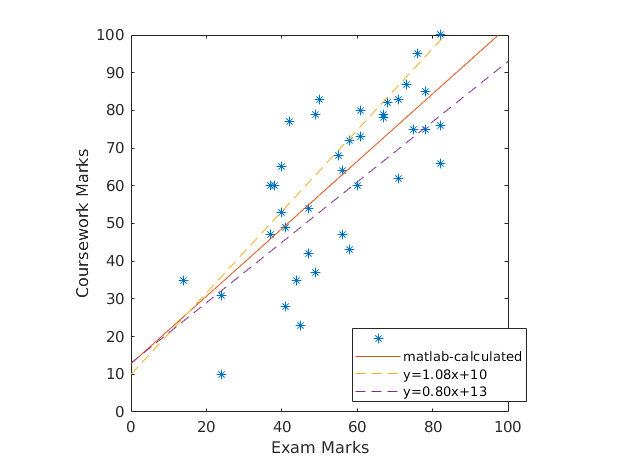

xfit=0:100; yfit=polyval(p,xfit); %Line of best fit
plot(xfit,yfit)
plot(i,10+i.*1.08, '--'); %max slope
plot(i,13+i.*0.80, '--'); %min slope
legend('', 'matlab-calculated', 'y=1.08x+10', 'y=0.80x+13', 'Location', 'best')
hold off;

print('eps/topic1_c.eps','-depsc')